Read raw features from the .xlsx

meanf = readtable("C:\Users\Zhehao\Dropbox (OIST)\My_Luscinia\meanf.xlsx",'Range','');
meanf = table2array(meanf);

ff = readtable("C:\Users\Zhehao\Dropbox (OIST)\My_Luscinia\ff.xlsx",'Range','');
ff = table2array(ff);

ffc = readtable("C:\Users\Zhehao\Dropbox (OIST)\My_Luscinia\ffc.xlsx",'Range','');
ffc = table2array(ffc);

harmo = readtable("C:\Users\Zhehao\Dropbox (OIST)\My_Luscinia\harmonicity.xlsx",'Range','');
harmo = table2array(harmo);

Generate dissimilarity matrix


fea = {'meanf','ff','ffc','harmo'};
weight = [1,1,1,1];

distcollect = {};
for trump = 1: length(fea)
    
    eval(['feature = ',fea{trump},';']);
    
    
    dist = [];
    for a = 1: length(feature)
        for b = 1: length(feature)
            alpha = rmmissing(feature(a,:));
            beta = rmmissing(feature(b,:));
            dist(a,b) = dtw(alpha,beta);
        end
    end
    
    dist01 = rescale(dist,0,1);
    distcollect{trump} = dist01;

end

distsum = zeros(size(distcollect{1}));
for biden = 1: length(distcollect)
    distsum = distsum + distcollect{biden}*weight(biden);
end

save('C:\Users\Zhehao\Dropbox (OIST)\My_Luscinia\dismatrix.mat','distsum');

Error using save
Must be a text scalar.

###  **After this setp, Use R to do the clustering**

### Construct the eleinf (a struct named element information)

Stress is 




%%%%%%%%%% another section
% read exported song
wavs = extract.filename("C:\Users\Zhehao\Dropbox (OIST)\My_Luscinia\ExportedSong",'*.wav');

for w = 1: length(wavs)
    [song(w).y,song(w).fs] = audioread(wavs{w});
    [~,song(w).name,~] = fileparts(wavs{w});
end

% element inf 
rawinf = table2struct(readtable("C:\Users\Zhehao\Dropbox (OIST)\My_Luscinia\eleinf.csv"));


% construct the element inf structure
eleinf = struct;
for e = 1: length(rawinf)
    
    eleinf(e).sound = rawinf(e).SongName;
    eleinf(e).number = rawinf(e).ElementNumber; % element number
    songidx = find(~cellfun(@isempty, regexp([song(:).name].', eleinf(e).sound)));
    songy = song(songidx).y;
    eleinf(e).initial = rawinf(e).StartTime*0.001*song(songidx).fs;
    eleinf(e).terminal = (rawinf(e).StartTime+rawinf(e).Length)*0.001*song(songidx).fs;
    eleinf(e).y = songy( eleinf(e).initial: eleinf(e).terminal);
    
end


% Optional, convert sylinf to new sylinf

[dims,stress] = mdscale(distsum,10);  % dimensions in the mds non-paramteric\

disp(['Stress is',stress]);

dimscell = num2cell(dims,2); % convert dims matrix to cell
[eleinf.dims] = dimscell{:};

### Add cluster info ( which cluster each element belongs to) to the eleinf

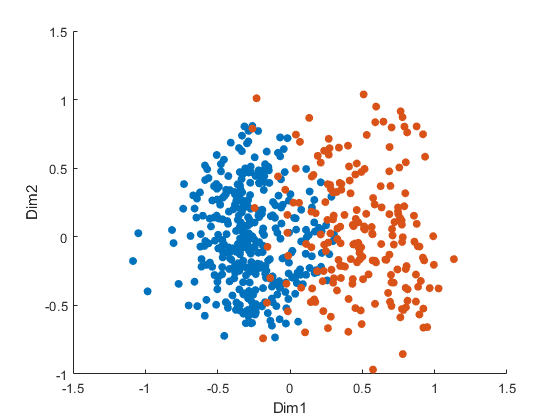

% this is for clusteirng syllables using kmedoids clustering method

load("C:\Users\Zhehao\Dropbox (OIST)\My_Luscinia\clusterinfo.mat");
cluidx = clun;
nclu = length(unique(clun)); % cluster to several clusters
%cluidx = kmedoids(dims,nclu);

cluidxcell = num2cell(cluidx,2); % convert dims matrix to cell

% convert eleinf to new eleinf
[eleinf.cluidx] = cluidxcell{:};

% merge pamx and pamy
pam = horzcat(pamx,pamy);
pam = num2cell(pam,2);
[eleinf.pam] = pam{:};

figure('Color','w');
for i = 1: nclu
    thisclu = find(cluidx==i);
    scatter(dims(thisclu,1),dims(thisclu,2),'filled');
    hold on
end
xlabel('Dim1'); ylabel('Dim2')

### Run inspect ele/syl/cluster function

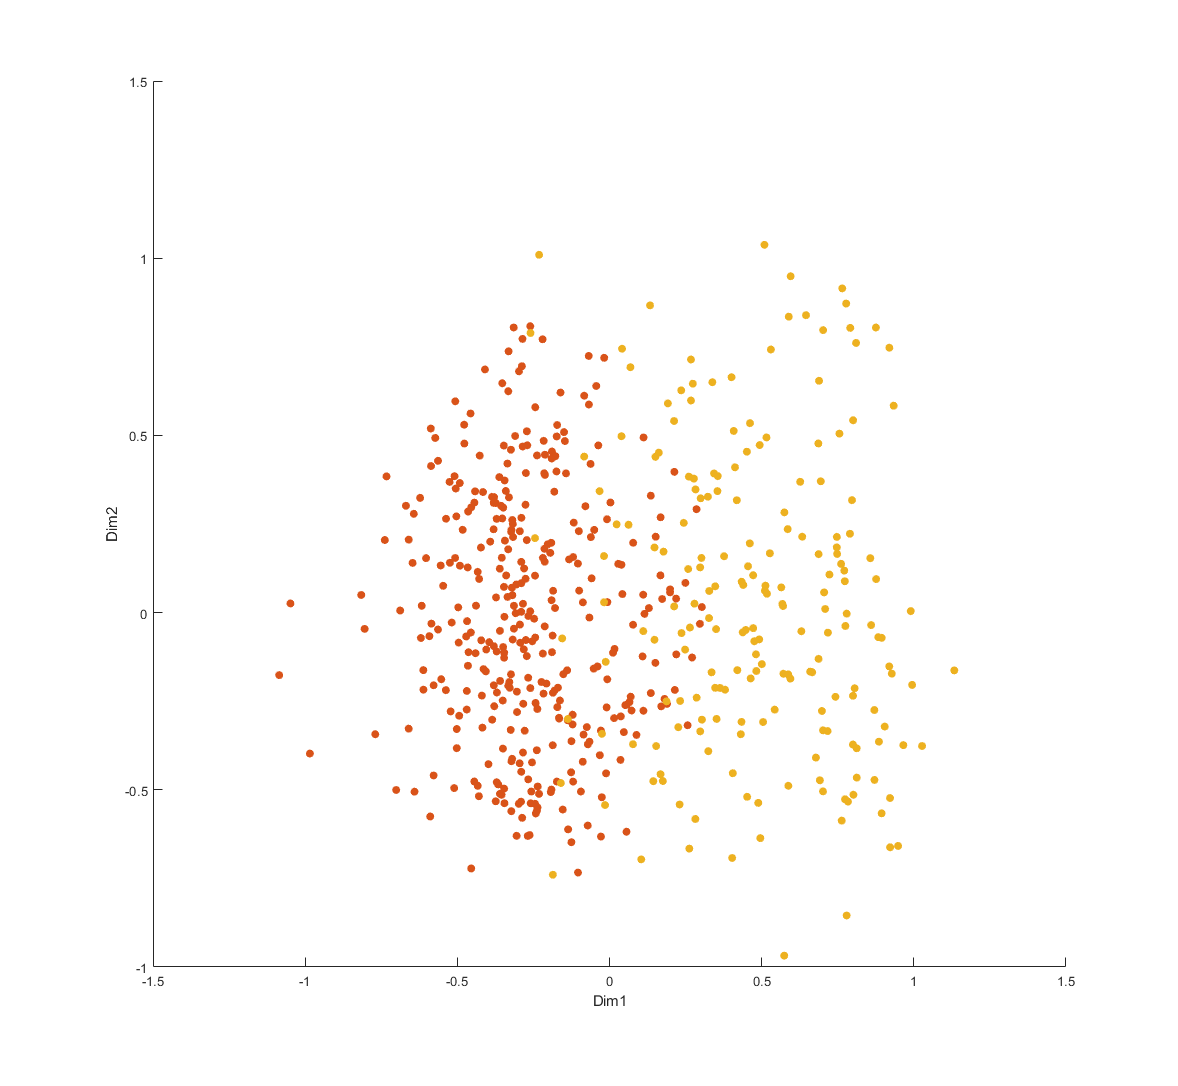

inspectcluster(eleinf) % check with NMDS dims-1,2


% OR
inspectpam(eleinf)  % check with PAM dims (only 2)